这个代码只需要修改bizhi，pianyi，qujianend。其他不要动。lEpsilon的值为色散厚度T，pianyi为白光干涉信号区间起点，qujianend为白光干涉信号区间终点。当白光干涉信号不在框内时可修改。必须保证框内有且仅有一个白光干涉信号。

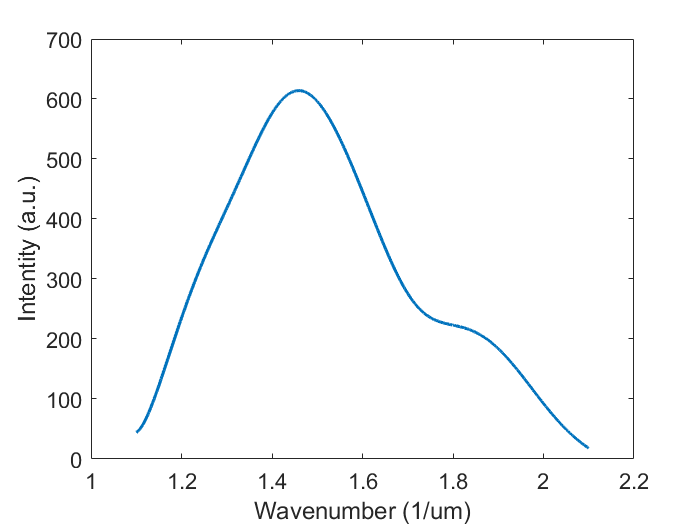

clc; clear all;
%显示光谱信息
format long
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency1 = (spectrum{:,1})';
spectrum_intensity1 = (spectrum{:,2})';
%disp("全部光谱信息");
% plot(spectrum_frequency,spectrum_intensity)
%找出探测器对应的光谱，这里假设是1.1-2.1
%找出探测器对应的光谱，这里假设是1.1-2.1
spectrum_frequency = linspace(spectrum_frequency1(1),spectrum_frequency1(end),40*length(spectrum_frequency1)); 
%光谱强度三次样条插值
spectrum_intensity = spline(spectrum_frequency1,spectrum_intensity1,spectrum_frequency);

[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
%disp("需要的光谱信息");
plot(spectrum_frequency,spectrum_intensity,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;

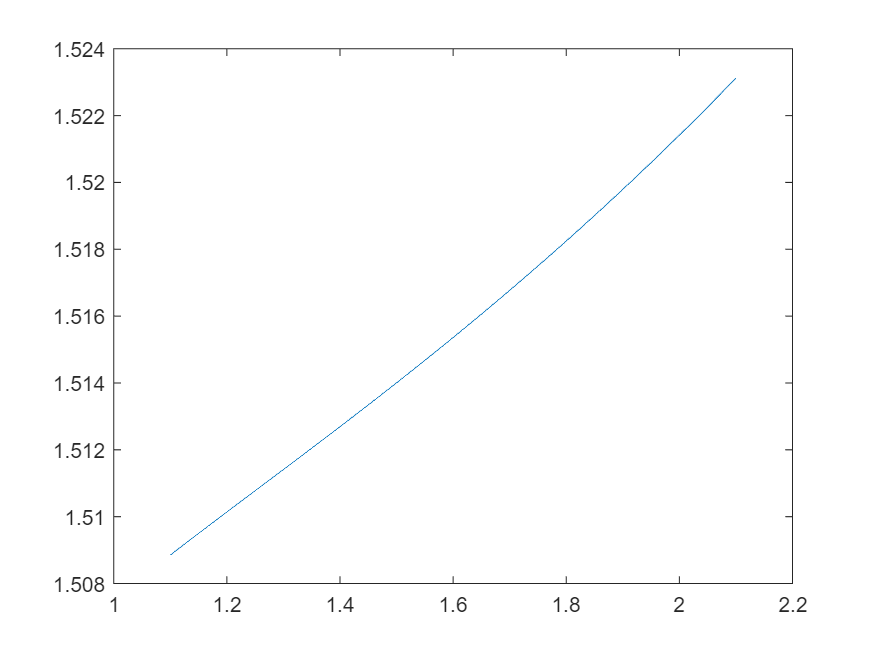


lambda = 1./spectrum_frequency;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%折射率曲线
%disp("折射率曲线");
plot(spectrum_frequency,index);

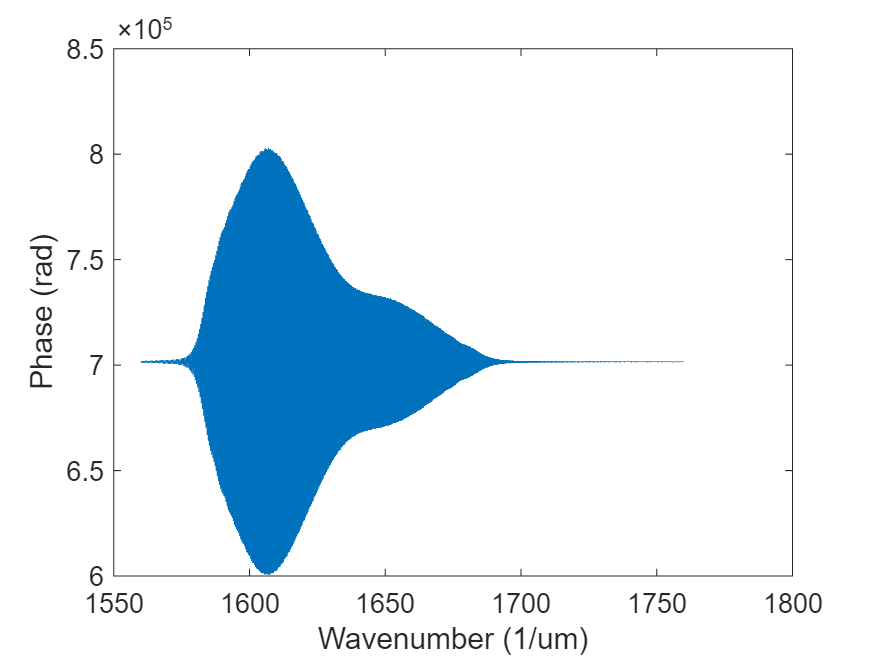

%色散
T = 2000;
bizhi = 1.5;
lEpsilon = T*bizhi; %单位为微米
z0 = 10;    %单位为微米
qujianend = 10+bizhi*1100+100;
N = qujianend*100;
pianyi = 10+bizhi*1100-100;
z = 0+pianyi:qujianend/N:(N-1)*(qujianend/N);
interference_signal1 = zeros(1,length(z));
for i = 1:length(z)
        interference_signal1(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency-...
        4*pi*(index-1).*spectrum_frequency*lEpsilon));
end
%disp("生成有色散的白光干涉信号");
plot(z,interference_signal1);
% plot(spectrum_frequency,Phase,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Phase (rad)')
ax = gca;
ax.FontSize = 13;

可见度

interference_signal = interference_signal1-mean(interference_signal1);
V = calcuV(interference_signal)

V =    0.006854086731119


白光干涉信号条纹长

W = calcuW(z,interference_signal1)

W =      1.191749637696994e+02


直接求解最大值：

[~, loc]=max(interference_signal1);
zhijie = z(loc)

zhijie =      1.606970000000000e+03


采用相干峰寻址法测量：高斯包络拟合法（白光干涉光强曲线符合高斯包络调制，对白光 干涉光强的高斯包络进行拟合，取其极值点的横坐 标就是该点对应的相干峰的坐标）

interference_signal = interference_signal1-mean(interference_signal1);
baoluo = hilbert(interference_signal); % Hilbert变换
baoluo = abs(baoluo);
plot(z,interference_signal);
guass = fit(z.',baoluo.','gauss1')

guass =      General model Gauss1:
     guass(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =   9.509e+04  (9.471e+04, 9.548e+04)
       b1 =        1611  (1611, 1611)
       c1 =       27.69  (27.56, 27.82)

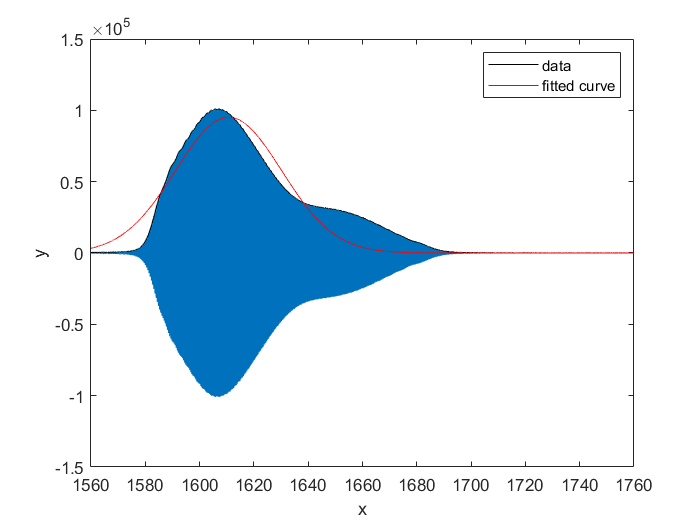

hold on
plot(guass,z,baoluo,'-k')
hold off

baoluoguass = guass.b1

baoluoguass =      1.610675295506094e+03


%重心法：

interference_signal = interference_signal1;
zhongxin = zxf(interference_signal);
zhongxin = round(zhongxin);
zhongxin = z(zhongxin)

zhongxin =      1.615440000000000e+03


插值法

interference_signal = interference_signal1-mean(interference_signal1);
[pks,locs,w,p] = findpeaks(interference_signal);
[~,loc1] = max(pks)

loc1 =    114


IDX= loc1-1:loc1+1;
poly = polyfit(z(locs(IDX)),interference_signal(locs(IDX)),2)

poly = 	1.0e+10 *

   -0.0000    0.0013   -1.0491


chazhi = -poly(2)/(2*poly(1))

chazhi =      1.607050588414351e+03


% hold off
% poly = polyfit(locs(IDX),pks(IDX),2)
% chazhi = -poly(2)/(2*poly(1))

基于相位的测量方法：傅里叶变换法:傅里叶正变换后选择其正频率部分，然后再进行傅里叶逆变换就会得到白光干涉信号的幅度谱和相位谱。从傅里叶变换法来看，有色散的白光干涉信号（复数形式）的幅度谱最大值所在位置和相位谱零点所在位置并不相等。

%对光谱进行傅里叶变换
interference_signal = interference_signal1-mean(interference_signal1);
% plot(z,interference_signal);
%fft补零
Nftt = 2^14;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(qujianend/N);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
Nifft = 2^22;
f_interference_signal = ifft(f_interference_signal(1:numel(f_interference_signal)/2),Nifft);
interference_signal = ifftshift(f_interference_signal);
deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
deltaZ = 1/(2*Nifft*deltaSigma);
z = (0:Nifft-1)*deltaZ;
intensity_fft = abs(interference_signal);
angle_fft = angle(interference_signal);
%坐标变换
z = z-z(end)/2;
intensity = intensity_fft;
zData = z;
phase = angle_fft;
[~,index3]= max(intensity);
za1 = zData(index3);
%-----------------------------------
[~,indexend] = min(abs(zData-(za1+0.5)));
[~,indexstart] = min(abs(zData-(za1-0.5)));
unwrapZend = zData(indexend);
unwrapZ_1 = zData(indexstart);
unwrapN1 = index3;
unwrapNe = find(zData==unwrapZend);
unwrapN_1 = find(zData==unwrapZ_1);
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index3);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
if za1<0
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N-zData(end)+pianyi
za1 = za1-zData(end)+pianyi
zData = zData - zData(end);
else
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N+pianyi
za1+pianyi
end

zp1 =      1.607315777613998e+03


ans =      1.607165605468750e+03


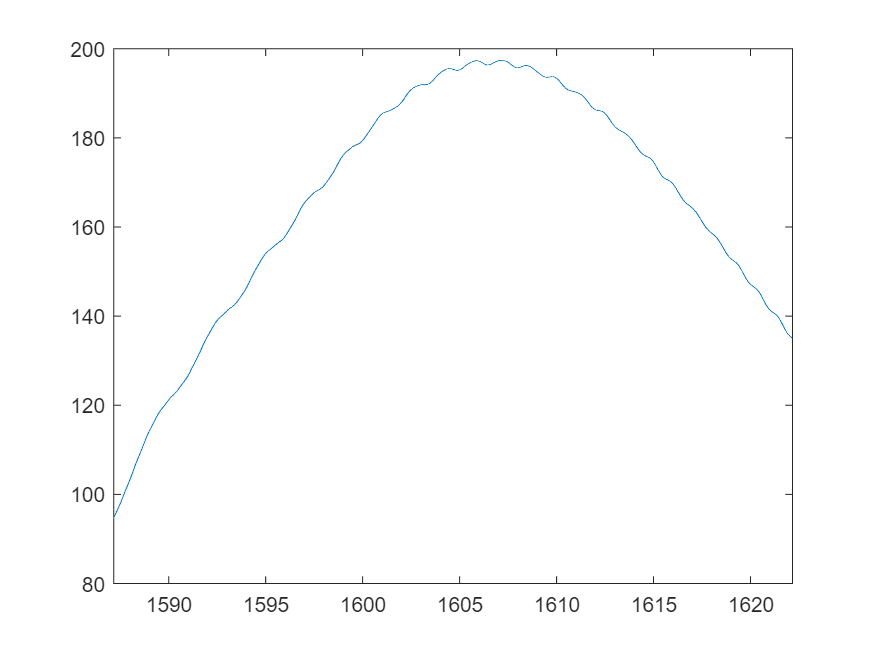

zData = zData+pianyi;
plot(zData,intensity);xlim([zData(index3)-20 zData(index3)+15]);

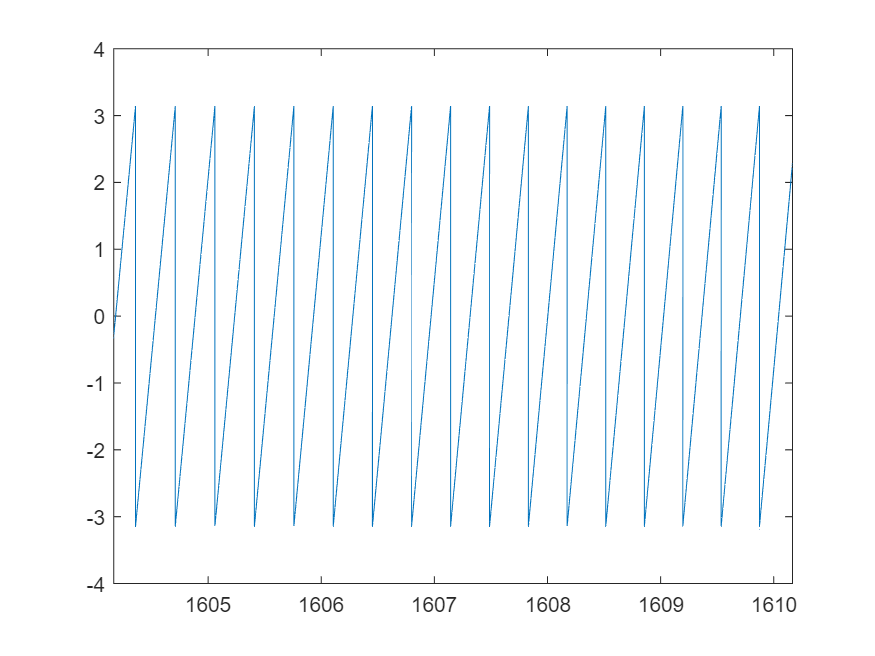

plot(zData,phase);xlim([zData(index3)-3 zData(index3)+3]);

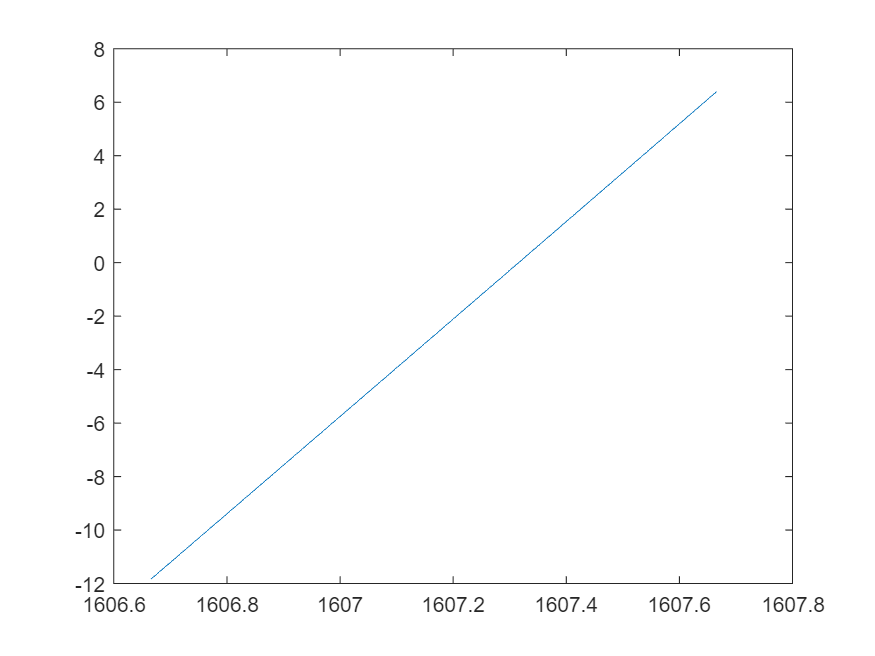

plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));

function center1 = zxf(I3)
I_V=diff(I3);
I_V1=I_V.^2;
xx=1:length(I_V1);
center1=sum(I_V1.*xx)/sum(abs(I_V1));
end

%零级条纹与第一级条纹的可见度
function V = calcuV(interference_signal1)
interference_signal = interference_signal1-mean(interference_signal1);
[pks,locs,~,~] = findpeaks(interference_signal);
[~,loc1] = max(pks);
IDX = loc1-1;
if interference_signal(locs(loc1-1))>interference_signal(locs(loc1+1))
    IDX = loc1+1;
end
V = (interference_signal(locs(loc1))-interference_signal(locs(IDX)))/interference_signal(locs(loc1));
end

%计算干涉条纹的空间长度
function wdt = calcuW(z,signal)
signal = signal-mean(signal);
%得到信号包络
W = hilbert(signal); % Hilbert变换
W = abs(W);
% plot(z,signal,z,W,'--','linewidth',1.5)
idx = find(diff(sign(W-max(W)/100)));
    for n = 1:numel(idx)
        idxrng = idx(n)-2:idx(n)+2;
        xfwhm(1,n) = interp1(W(idxrng), z(idxrng), max(W)/100, 'pchip');
    end
    wdt = xfwhm(end)-xfwhm(1);
end